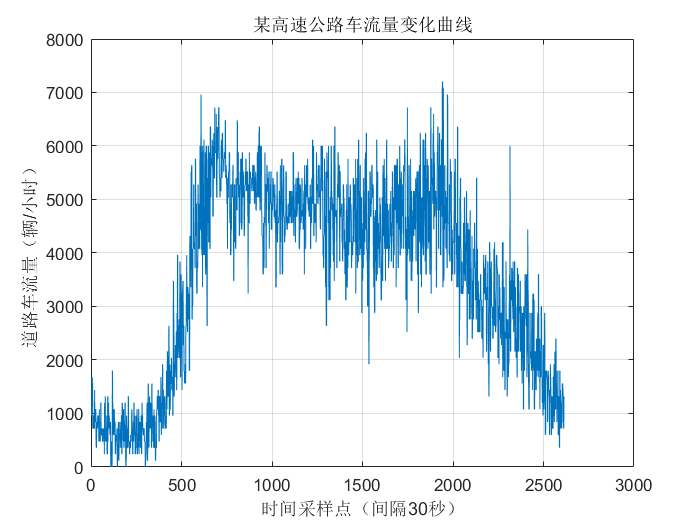

clear;
close all;

% 数据可视化
load data.mat;
figure(1),
plot(data),
xlabel('时间采样点（间隔30秒）'),
ylabel('道路车流量（辆/小时）'),
title('某高速公路车流量变化曲线'),
grid on;

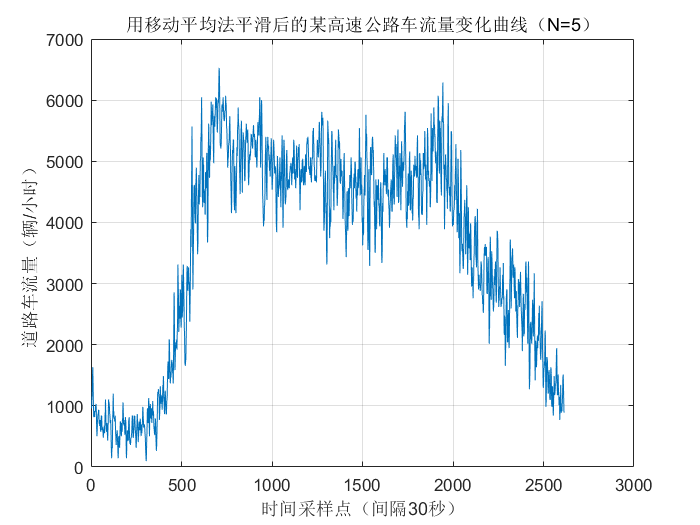


% 移动平均法
% N=5
N=5;
len=size(data,1);
Move_avr1=zeros(len,1);
sum1=0;
for i=1:N
    sum1=sum1+data(i);
    Move_avr1(i)=sum1/i;
end
for i=N+1:len
    sum1=0;
    for j=1:N
        sum1=sum1+data(i-j);
    end
    Move_avr1(i)=sum1/N;
end
figure(2),
plot(Move_avr1),
xlabel('时间采样点（间隔30秒）'),
ylabel('道路车流量（辆/小时）'),
title('用移动平均法平滑后的某高速公路车流量变化曲线（N=5）'),
grid on;

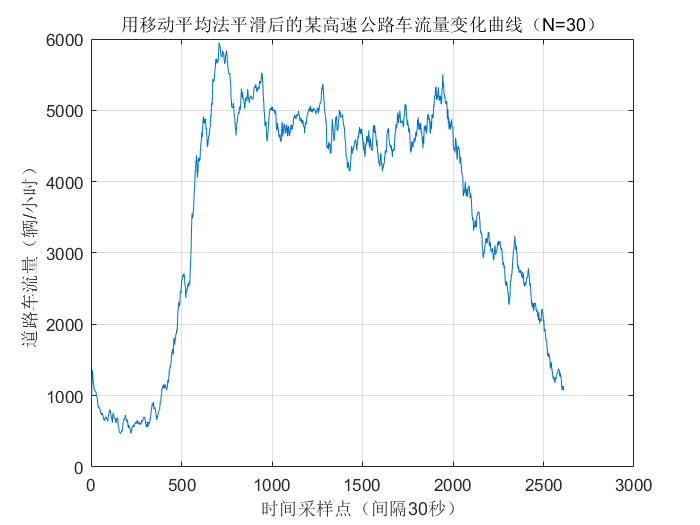


% N=30
N=30;
Move_avr2=zeros(len,1);
sum1=0;
for i=1:N
    sum1=sum1+data(i);
    Move_avr2(i)=sum1/i;
end
for i=N+1:len
    sum1=0;
    for j=1:N
        sum1=sum1+data(i-j);
    end
    Move_avr2(i)=sum1/N;
end
figure(3),
plot(Move_avr2),
xlabel('时间采样点（间隔30秒）'),
ylabel('道路车流量（辆/小时）'),
title('用移动平均法平滑后的某高速公路车流量变化曲线（N=30）'),
grid on;

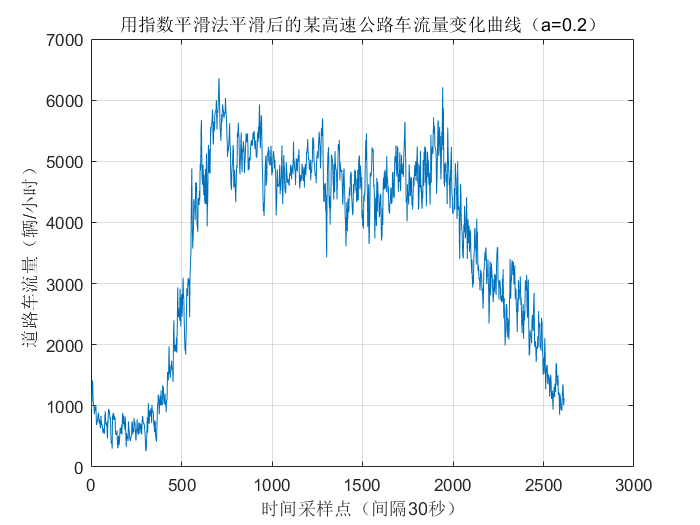


% 指数平滑法
% a=0.2
a=0.2;
Idx1=zeros(len,1);
tmp=zeros(len+1,1);
tmp(1)=(data(1)+data(2)+data(3))/3;
for i=2:len+1
    tmp(i)=a*data(i-1)+(1-a)*tmp(i-1);
    Idx1(i-1)=tmp(i);
end
figure(4),
plot(Idx1),
xlabel('时间采样点（间隔30秒）'),
ylabel('道路车流量（辆/小时）'),
title('用指数平滑法平滑后的某高速公路车流量变化曲线（a=0.2）'),
grid on;

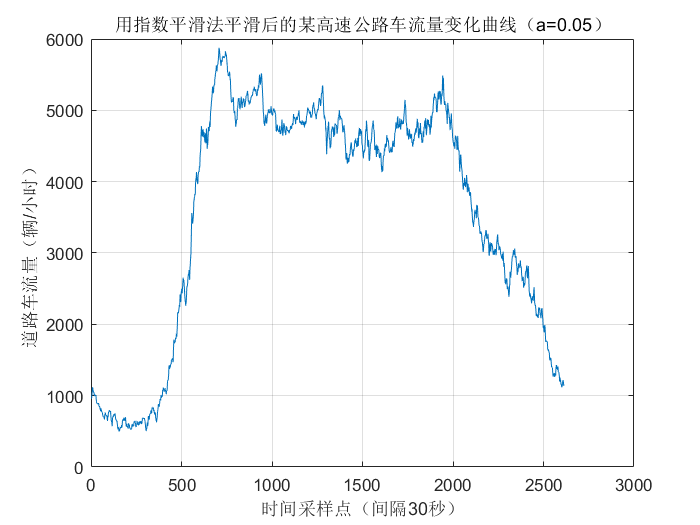


% a=0.05
a=0.05;
Idx2=zeros(len,1);
tmp=zeros(len+1,1);
tmp(1)=(data(1)+data(2)+data(3))/3;
for i=2:len+1
    tmp(i)=a*data(i-1)+(1-a)*tmp(i-1);
    Idx2(i-1)=tmp(i);
end
figure(5),
plot(Idx2),
xlabel('时间采样点（间隔30秒）'),
ylabel('道路车流量（辆/小时）'),
title('用指数平滑法平滑后的某高速公路车流量变化曲线（a=0.05）'),
grid on;


% % ARIMA
% % 平稳性检验
% adf_res1=adftest(data);
% kpss_res1=kpsstest(data);
% 
% % 差分
% data_diff=diff(data);
% adf_res2=adftest(data_diff);
% kpss_res2=kpsstest(data_diff);
% figure(6),plot(data_diff),title('车流量差分图');
% 
% % 自相关函数和偏自相关函数
% figure(7),autocorr(data_diff);
% figure(8),parcorr(data_diff);
% 
% % 确定p和q
% p=5;
% d=0;
% q=5;
% 
% % 残差检验
% Options=optimoptions(@fmincon,'MaxIter',2000,'MaxFunEvals',2000,...
%     'Display','notify','TolCon',1e-12,'TolFun',1e-12,'TolX',1e-12);
% Mdl=arima(p,d,q);
% EstMdl=estimate(Mdl,data_diff);
% [res,~,logL]=infer(EstMdl,data_diff);
% 
% stdr = res/sqrt(EstMdl.Variance);
% figure(9),
% subplot(2,3,1),plot(stdr),
% subplot(2,3,2),histogram(stdr),
% subplot(2,3,3),autocorr(stdr),
% subplot(2,3,4),parcorr(stdr),
% subplot(2,3,5),qqplot(stdr);
% 
% diffRes0 = diff(res);  
% SSE0 = res'*res;
% DW0 = (diffRes0'*diffRes0)/SSE0;

% 单步
% pred_diff=zeros(len+1,1);
% pred_diff(1:2)=0;
% for i=2:len-1
%     pred_diff(i)=forecast(EstMdl,1,data_diff(1:i));
% end
% figure(10),
% plot(data_diff),
% grid on,
% hold on,
% plot(pred_diff),
% grid on;
% 
% % 差分还原
% pred_data=zeros(len,1);
% for i=1:len
%     pred_data(i)=data(1)+sum(data_diff(1:(i-1)))+pred_diff(i);
% end
% figure(11),plot(data),
% grid on,
% hold on,
% plot(pred_data),
% hold off;
% figure(12),plot((pred_data-data)/data),
% grid on;